%WING AND ENGINE SIZING
u = symunit;  % u_c = double(separateUnits(unitConvert(100*u.knot, u.m/u.s))),% knot-->m/s / cruise speed, m/s
e = 0.85; 
c_D0 = 0.03;
sigma = 0.861; 
AR = 7;
eta = 0.7; 
c_Lmax = 1.5; 
C_DG=0.06; 
C_LR=1.24; 
miu = 0.04;               
V_max = 129.59 * u.knot; 
v_s = 431.965*u.knot; 
m = 1763.698*u.lb;                                                                                                                  
ro_0 = 0.002378*u.slug/u.ft^3;
ro = 0.002048*u.slug/u.ft^3; 
ro_C = 0.001755*u.slug/u.ft^3;                                                                  
g = 32.1850*u.ft/u.s^2;
S_TO = 1312.34*u.ft;
ROC = 984.252*u.ft/u.s;                                                                                               
% SI
ro_ = double(separateUnits(unitConvert(ro,'SI'))); ro_0_ = double(separateUnits(unitConvert(ro_0,'SI')));
ro_C_ = double(separateUnits(unitConvert(ro_C,'SI')));
v_s_= double(separateUnits(unitConvert(v_s,'SI'))); V_max_=double(separateUnits(unitConvert(V_max,'SI')));
g_ = double(separateUnits(unitConvert(g, 'SI'))); S_TO_ = double(separateUnits(unitConvert(S_TO,'SI')));
ROC_ = double(separateUnits(unitConvert(ROC, 'SI'))); m_ = double(separateUnits(unitConvert(m,'SI'))); 

ro_0 = double(separateUnits(ro_0)); ro = double(separateUnits(ro)); ro_C = double(separateUnits(ro_C));
V_max = double(separateUnits(V_max)); v_s = double(separateUnits(v_s)); m = double(separateUnits(m));                           
g = double(separateUnits(g)); S_TO = double(separateUnits(S_TO)); ROC = double(separateUnits(ROC));
%STALL SPEED
 WS_stall = 0.5 * ro * (v_s * 1.688)^2 * c_Lmax; WS_stall = double(separateUnits(WS_stall));
% SI
WS_stall_ = 0.5 * ro_ *v_s_^2 * c_Lmax        %(N/m2)     

WS_stall_ = 3.9092e+04

%MAXIMUM SPEED
K = 1 / (pi * e * AR) ;                                                                                                                                                                
WS = 0:1:90;                                                                                                                                                                                        
WP_Vmax = eta * 550 ./(0.5 * ro_0 * (V_max * 1.688)^3 * c_D0 ./WS + 2 * K / (ro * sigma * (V_max * 1.688)) * WS);
% SI          
WS_ = 0:1:90;                                                                                         %SI (N/M^2)  ;                                                                          
WP_Vmax_ = eta ./(0.5 * ro_0_ * V_max_^3 * c_D0 ./WS_ + 2 * K / (ro_ * sigma * V_max_) * WS_);     % SI (N/W);

%TAKEOFF RUN
 V_TO = 1.1 * v_s;
WP_STO = (1 - exp(0.6 * ro * g * C_DG * S_TO ./ WS)) ./ (miu -(miu + C_DG / C_LR) * exp(0.6 * ro * g * C_DG * S_TO ./ WS)) * eta / V_TO/1.688 * 550;
% SI
V_TO_ = 1.1 * v_s_ ;                                                                                                                                                                        
WP_STO_ = (1 - exp(0.6 * ro_ * g_ * C_DG * S_TO_ ./ WS_)) ./ (miu -(miu + C_DG / C_LR) * exp(0.6 * ro_ * g_ * C_DG * S_TO_ ./ WS_)) * eta / V_TO_

WP_STO_ =        NaN    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0324    0.0323    0.0323    0.0323    0.0323    0.0323    0.0323    0.0322    0.0322    0.0322    0.0321    0.0321    0.0321    0.0320    0.0320    0.0320    0.0319    0.0319    0.0318    0.0318    0.0317    0.0317    0.0316    0.0316    0.0315



%RATE OF CLIMB
LD_max = 1 / 2 / sqrt(K * c_D0);
WP_ROC = 1 ./ (ROC / 60 / eta + sqrt(2 / (ro * sqrt(3 * c_D0 / K)) * WS) * (1.155 / LD_max / eta)) * 550;
% SI
WP_ROC_ = 1 ./ (ROC_ / 60 / eta + sqrt(2 / (ro_ * sqrt(3 * c_D0 / K)) * WS_) * (1.155 / LD_max / eta))

WP_ROC_ =     0.1400    0.1369    0.1357    0.1348    0.1340    0.1333    0.1327    0.1322    0.1317    0.1312    0.1308    0.1303    0.1299    0.1296    0.1292    0.1288    0.1285    0.1282    0.1279    0.1276    0.1273    0.1270    0.1267    0.1264    0.1262    0.1259    0.1257    0.1254    0.1252    0.1249    0.1247    0.1245    0.1243    0.1241    0.1238    0.1236    0.1234    0.1232    0.1230    0.1228    0.1226    0.1225    0.1223    0.1221    0.1219    0.1217    0.1216    0.1214    0.1212    0.1210


%ABSOLUTE CEILING
sigma_C = ro_C / ro_0  ;                                                                                                                                                                       
WP_C = sigma_C ./ (sqrt(2 / (ro_C * sqrt(3 * c_D0 / K)) * WS) * (1.155 / LD_max / eta)) * 550;
% SI
sigma_C_ = ro_C_ / ro_0_  ;                                                                                                                                                                 
WP_C_ = sigma_C_ ./ (sqrt(2 / (ro_C_ * sqrt(3 * c_D0 / K)) * WS_) * (1.155 / LD_max / eta))

WP_C_ =        Inf    4.2755    3.0232    2.4685    2.1378    1.9121    1.7455    1.6160    1.5116    1.4252    1.3520    1.2891    1.2342    1.1858    1.1427    1.1039    1.0689    1.0370    1.0077    0.9809    0.9560    0.9330    0.9115    0.8915    0.8727    0.8551    0.8385    0.8228    0.8080    0.7939    0.7806    0.7679    0.7558    0.7443    0.7332    0.7227    0.7126    0.7029    0.6936    0.6846    0.6760    0.6677    0.6597    0.6520    0.6446    0.6374    0.6304    0.6236    0.6171    0.6108


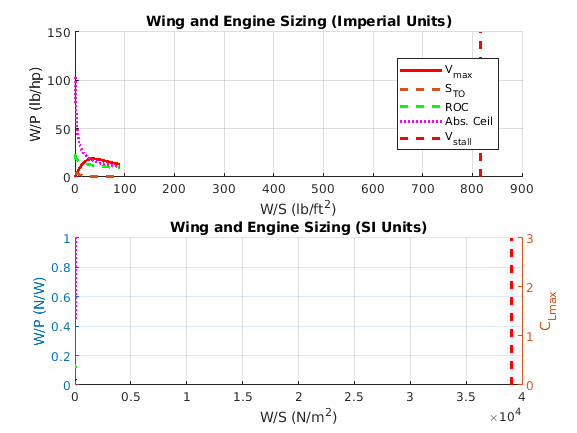


%WING AND ENGINE SIZING DIAGRAM
figure;
sp1 =subplot(2,1,1); hold on;             
    plot(WS,WP_Vmax, 'r-','lineWidth',2); plot(WS,WP_STO,'--','lineWidth',2);                                                                                      
    plot(WS,WP_ROC,'g--','linewidth',2); plot(WS,WP_C,'m:','linewidth',2);                                                                                         
    plot([WS_stall WS_stall],[0 400],'r--','LineWidth',2);                                                                                                                         
grid on; title('Wing and Engine Sizing (Imperial Units)'); xlabel('W/S (lb/ft^2)'); ylabel('W/P (lb/hp)'); ylim([0 150]);                          
legend({'V_{max}';'S_{TO}'; 'ROC';'Abs. Ceil';'V_{stall}'},'Location','best');                                                                                    
% SI
sp2=subplot(2,1,2); yyaxis left; hold on;                                                                                                                                             
    plot(WS_,WP_Vmax_,'r-','LineWidth',2); plot(WS_,WP_STO_,'b--','LineWidth',2);                                                                    
   plot(WS_,WP_ROC_,'g--','LineWidth',2); plot(WS_,WP_C_,'m:','LineWidth',2);                                                                            
    plot([WS_stall_ WS_stall_],[0 1],'r--','linewidth',2);                                                                 
grid on; title('Wing and Engine Sizing (SI Units)'); xlabel('W/S (N/m^2)'); ylabel('W/P (N/W)'); ylim([0 1]);                                     


%EVALUATION OF HIGH LIFT DEVICES INFLUENCE
V_stall_min_ = 0.5 * v_s_; 
v_stall_max_ = 1.1 * v_s_;
v_stall_=V_stall_min_:(v_stall_max_-V_stall_min_)/4:v_stall_max_;  
axes(sp2); 
yyaxis right;
hold on; 
ylim([0 3]); C_L_Stall =[]; 
ylabel('C_{Lmax}'); 
col=['b';'r';'y';'g';'m']; 
for i=1:length(v_stall_), C_L_Stall = 2 * WS_ / ro_ / v_stall_(i)^2; plot(WS_, C_L_Stall,'LineStyle','-.','Color',col(i),'Marker','none'); end                              


%DESIGN POINT [W/S_OPT, W/P_OPT]  Imperial Units
Obj = @(x, WS, WP_Vmax, WP_STO, WP_ROC, WP_C) ...                                                                                                               
        -min([interp1(WS,WP_Vmax,x),interp1(WS,WP_STO,x),interp1(WS,WP_ROC,x),interp1(WS,WP_C,x)]);               
   [WS_opt, WP_opt] = fmincon(@(x) Obj(x, WS, WP_Vmax, WP_STO, WP_ROC, WP_C), WS_stall/2,[],[],[],[],0, WS_stall_);        % design point

Error using barrier
Objective function is undefined at initial point. Fmincon cannot continue.

Error in fmincon (line 861)
    [X,FVAL,EXITFLAG,OUTPUT,LAMBDA,GRAD,HESSIAN] = barrier(funfcn,X,A,B,Aeq,Beq,l,u,confcn,options.HessFcn, ...

 disp(['Design Point: WS_opt = ' num2str(WS_opt) ' lb/hp;  WP_opt = ' num2str(-WP_opt) ' lb/hp']);                                                                  
 
 axes(sp1); yyaxis left; hold on; plot(WS_opt,-WP_opt,'bo','MarkerSize',10,"MarkerFaceColor",'b');                                                        
legend(sp1,{'V_{max}';'S_{TO}'; 'ROC';'Abs. Ceil';'V_{stall}';('WS_{opt}, WP_{opt}');...                                                                                 
    ['V_s=' num2str(v_stall_(1))];['V_s=' num2str(v_stall_(2))];['V_s=' num2str(v_stall_(3))];...                                                                      
     ['V_s=' num2str(v_stall_(4))];['V_s=' num2str(v_stall_(5))]},'Location','best');


%DESIGN POINT [W/S_OPT, W/P_OPT]
Obj = @(x, WS_, WP_Vmax_, WP_STO_, WP_ROC_, WP_C_) ...                                                                                                               
        -min([interp1(WS_,WP_Vmax_,x),interp1(WS_,WP_STO_,x),interp1(WS_,WP_ROC_,x),interp1(WS_,WP_C_,x)]);               
   [WS_opt, WP_opt] = fmincon(@(x) Obj(x, WS_, WP_Vmax_, WP_STO_, WP_ROC_, WP_C_), WS_stall/2,[],[],[],[],0, WS_stall_);        % design point
 disp(['Design Point: WS_opt = ' num2str(WS_opt) ' N/m2;  WP_opt = ' num2str(-WP_opt) ' N/W']);                                                                  
 
 axes(sp2); yyaxis left; hold on; plot(WS_opt,-WP_opt,'bo','MarkerSize',10,"MarkerFaceColor",'b');                                                        
legend(sp2,{'V_{max}';'S_{TO}'; 'ROC';'Abs. Ceil';'V_{stall}';('WS_{opt}, WP_{opt}');...                                                                                 
    ['V_s=' num2str(v_stall_(1))];['V_s=' num2str(v_stall_(2))];['V_s=' num2str(v_stall_(3))];...                                                                      
     ['V_s=' num2str(v_stall_(4))];['V_s=' num2str(v_stall_(5))]},'Location','best');

%DESIGHN OF UNMANNED AERIAL SYSTEMS
WPd=2/4.3;
WSd=2/2.96;
WP_ceil = 0.738 * 550 / sqrt(2 /0.001755 / sqrt(3 * 0.03 / 0.053) *  WSd) / (1.155 / 12.48 / 0.7)
WP_Vmax = 0.7 *  550 / (0.5 * 0.002378 * (25 * 1.688)^3 *0.03 / WSd + 2 * 0.053 / (0.002048 * 0.861 * (25 * 1.688)) * WSd)
WP_ROC  = 1*550 / (150/60 / 0.7 + sqrt(2 / 0.002378 / sqrt(3*0.03 / 0.053) * WSd) *  1.155 / 12.48 / 0.7)
WP_STO  = (1 - exp(0.6 * 0.002048 * 32.2 * 0.023 * 80 / WSd)) / (0.04 - (0.04 + 0.023 / 1.24) *...
           exp(0.6 * 0.002048 * 32.2 * 0.023 * 80 / WSd)) * 0.7 / 13.2 / 1.688 * 550